# Preparing Your Images for Classification

As discussed in the "Preparing Your Images for Classification" video, you need to prepare your imaging data and extract features before you are ready to train your model.

This reading will prepare a collection of concrete images for training and extract several intensity-based features. You will save your data and visualize your results. 

**The training and test data sets created by this script and the resulting feature table will be used in the next lesson.**

## Prepare Your Data

The data preparation step generally includes several operations:

- Create Labels

- Split into Training and Test Sets

- Image Processing

### Create Labels

To begin, you will create an image datastore using folder names as labels. Fortunately, in this case, the concrete data set has already been sorted into labeled folders. If you are working with an unlabeled training set, you may have to perform this step manually. 

`uigetdir` is a convenient way to retrieve the file path of your chosen folder for the datastore. You could also perform this step by typing out the file path, as we did in the "Preparing Your Images for Classification" video. 

**Run this section**  to choose the "Concrete" subfolder in the "Data" folder of the course download. You will then create a datastore using the names of the subfolders within "Concrete" ("Negative" and "Positive") as your labels. When prompted, **select the location of the "Concrete" data folder** from the downloaded course files.

fileLocation = uigetdir();
dsConcrete = imageDatastore(fileLocation,"IncludeSubFolders",true,"LabelSource","foldernames");
categories(dsConcrete.Labels)

ans = 2×1 cell array
    {'Negative'}
    {'Positive'}


Your output here should be 'Negative' and 'Positive.' If this is not the case, ensure that you have downloaded the course files correctly and have chosen the "Concrete" subfolder when prompted.

Rename the data labels to be more descriptive.

dsConcrete.Labels = renamecats(dsConcrete.Labels,["No Crack" "Crack"]);
categories(dsConcrete.Labels)

ans = 2×1 cell array
    {'No Crack'}
    {'Crack'   }


### Split into Training and Test Sets

The following line of code will randomly allocate 80% of each label into a subset used for training. The remaining 20% will be allocated to the test set. The test set will not be used in the remainder of this reading but will be important when you evaluate your trained model.

[dsTrain,dsTest] = splitEachLabel(dsConcrete,0.8,"randomize");
countEachLabel(dsTrain)

ans = 2×2 table
     Label      Count
    ________    _____

    No Crack     400 
    Crack        400 


You can see that because our initial data set had equal numbers of "Crack" and "No Crack" images, `splitEachLabel` has allocated the same number of images of each label to the training and test data sets. It is important to have similar numbers of each label in a training set; unbalanced classes may result in an error-prone model.

## Extract Features

To extract engineered features based on intensity, use the function created during the "Preparing Your Images for Classification" video. To review the function contents, open (but do not edit) `extractConcreteFeatures.m`.

concreteTable = extractConcreteFeatures(dsTrain);

If you run into errors at this step, make sure that the downloaded course files are added to your path.

## Save the Information Needed to Train a Model

**Make a note of your current folder; this is where this line of code will save your .mat file;** you will need it later.

save concreteIntensityFeatures.mat concreteTable dsTrain dsTest

## Visualize Results

Before you begin training, it is a good idea to visualize your data. Because a different random set of images was allocated to the training set, your features may look slightly different than those seen in the video.

You can use histograms to see the distribution of average intensities:

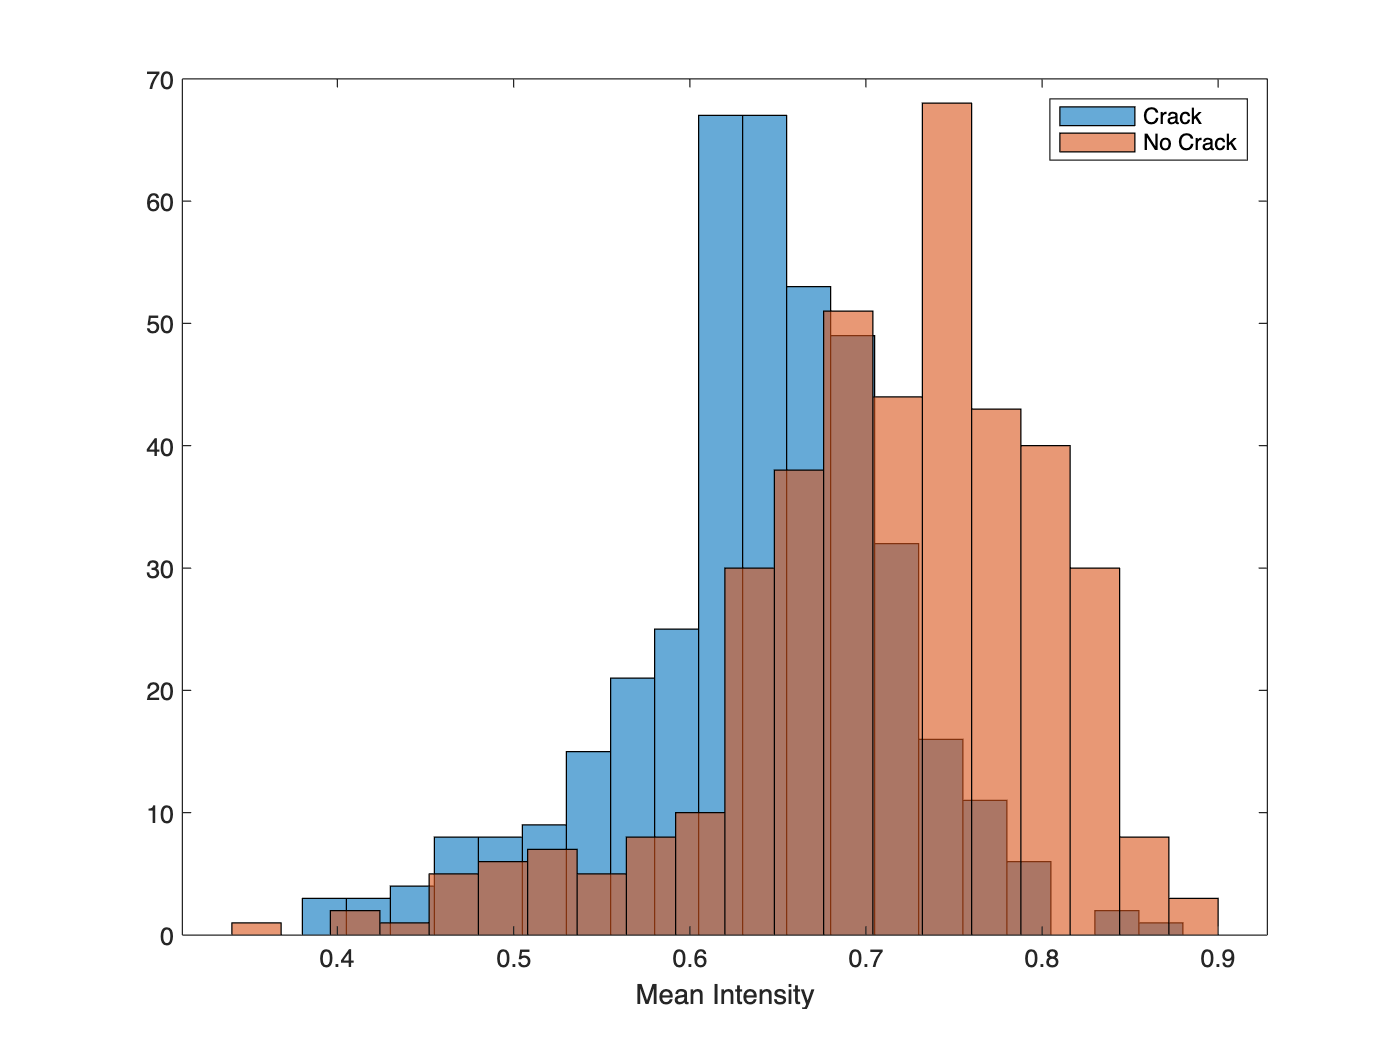

histogram(concreteTable.intensityAvg(concreteTable.label == "Crack"),20)
hold on
histogram(concreteTable.intensityAvg(concreteTable.label == "No Crack"),20)
hold off
xlabel("Mean Intensity")
legend("Crack","No Crack")

Create a similar histogram to see the distribution of standard deviation of intensity:

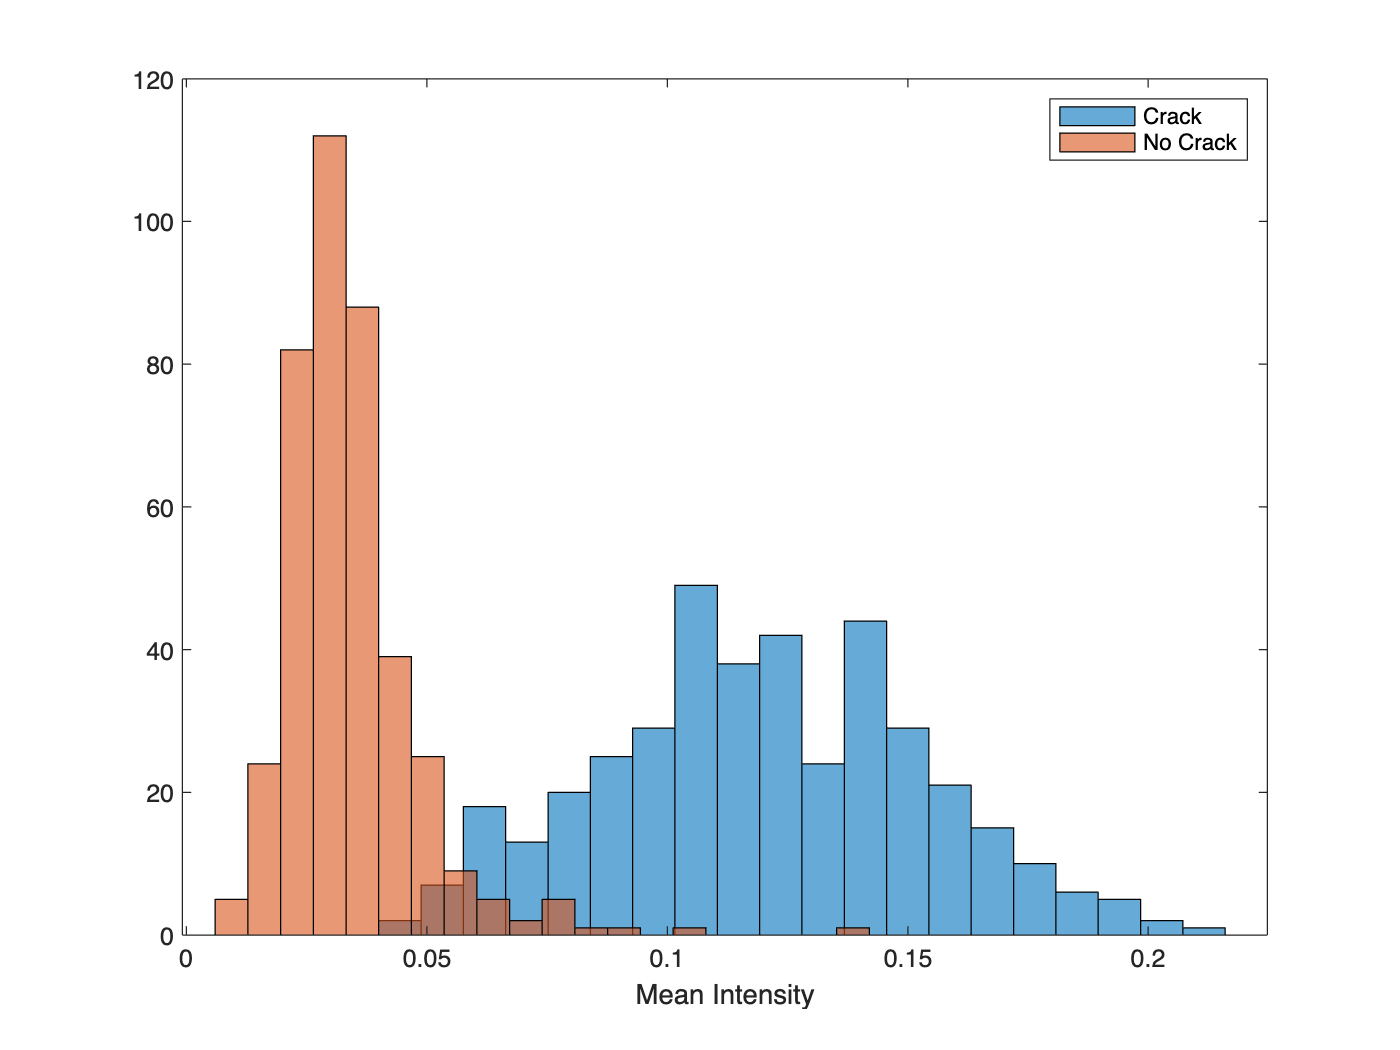

histogram(concreteTable.intensitySTD(concreteTable.label == "Crack"),20)
hold on
histogram(concreteTable.intensitySTD(concreteTable.label == "No Crack"),20)
hold off
xlabel("Mean Intensity")
legend("Crack","No Crack")

You should see differences between the distributions of mean intensity and standard deviation of intensity values in the "Crack" and "No Crack" concrete images. These metrics measure different aspects of the images; one metric is a better predictor of cracks than the other. 

In the video, you saw `gscatter` used to create a grouped scatter plot that showed both features simultaneously. Try this for your training set:

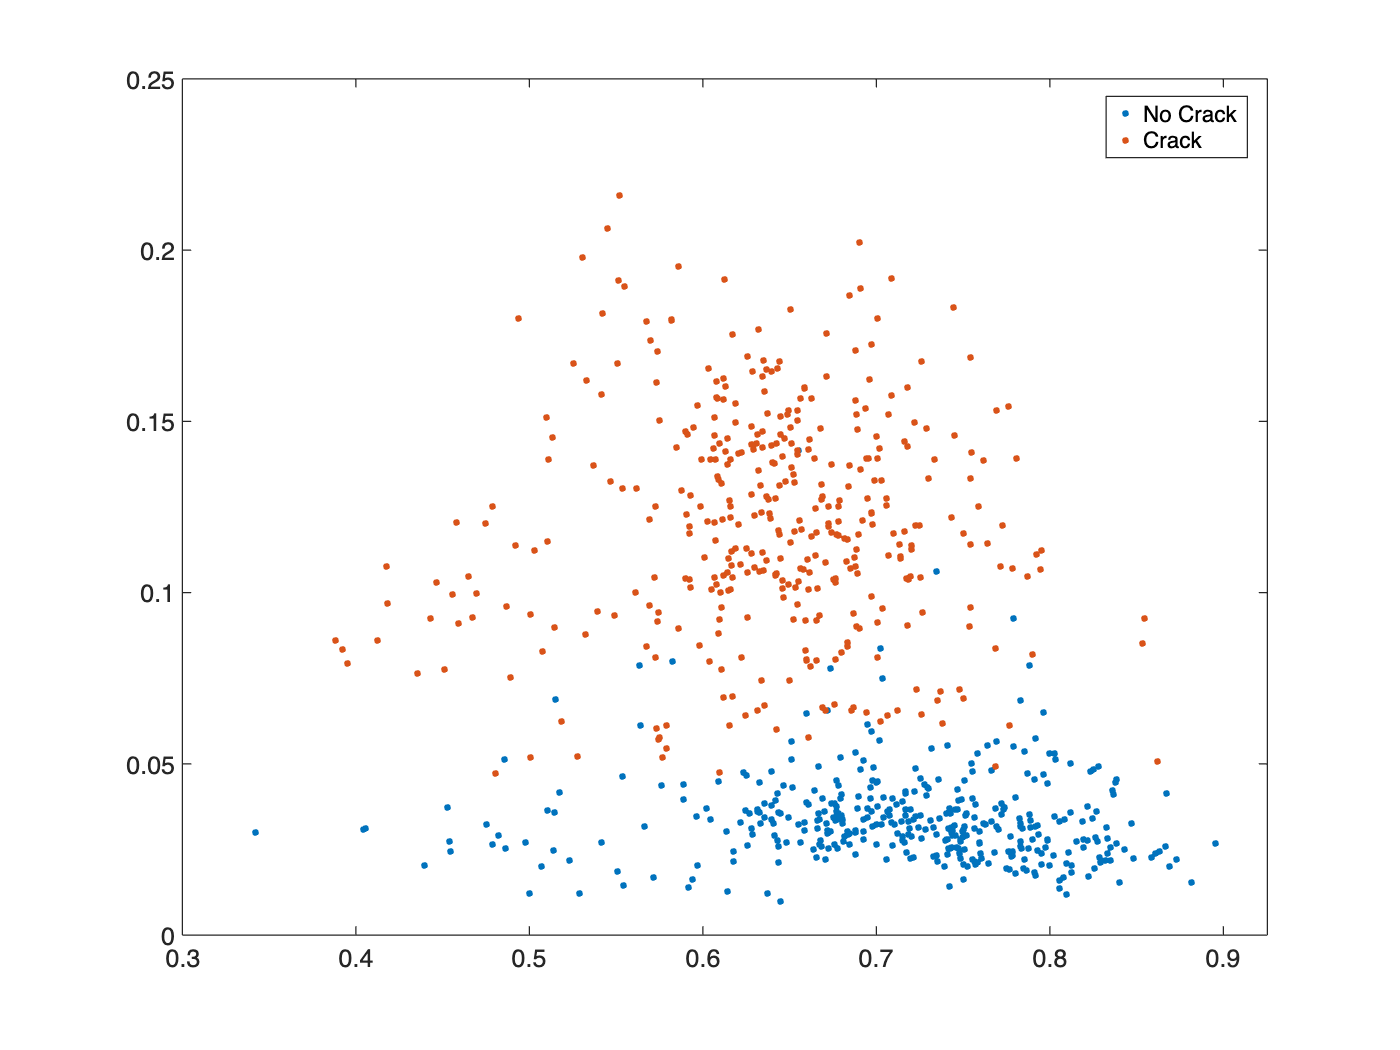

gscatter(concreteTable.intensityAvg, concreteTable.intensitySTD, concreteTable.label);

*Copyright 2022 The MathWorks, Inc.*